# Checking a CPACS v3 file

Add to Matlab Path: `<TIGL_INSTALL_DIR>/share/tigl3/matlab/`

## Get the file

clear all

fileName = 'CPACS_30_D150.xml';
try
     doc = xmlread(fileName);
catch err
     error('Failed to read CPACS file %s.',fileName);
end

## Parse the file

dataXYZ_A = getFuselageProfiles(doc);

Found 11 fuselageProfile nodes


Plots

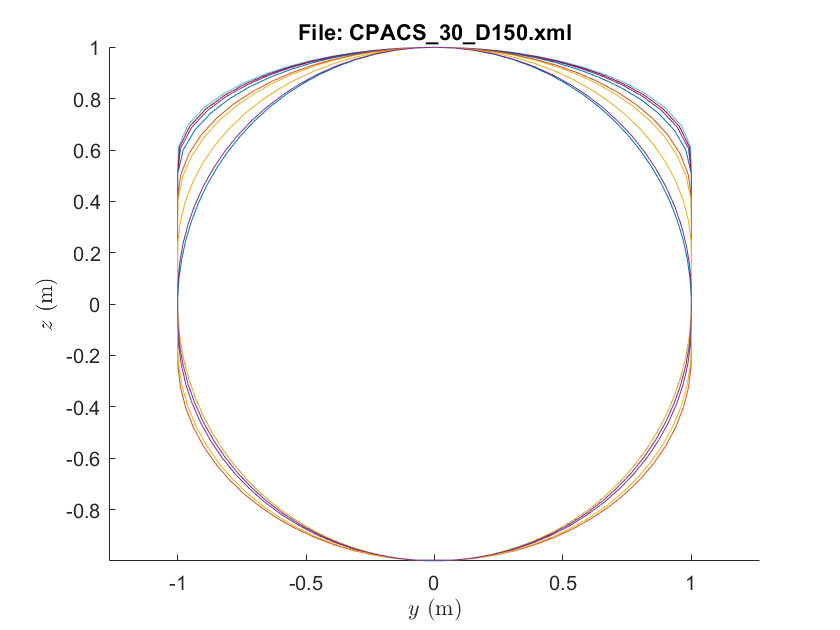

h1 = figure(1);
hold on
for i = 1:length(dataXYZ_A)
    axis equal
    plot(dataXYZ_A{i}(:,2),dataXYZ_A{i}(:,3))
end
title(sprintf('File: %s', fileName), 'Interpreter', 'none')
xlabel('$y$ (m)', 'Interpreter', 'latex'); 
ylabel('$z$ (m)', 'Interpreter', 'latex'); 
hold off

doc = [];
fileName = 'test01.xml';
try
     doc = xmlread(fileName);
catch err
     error('Failed to read CPACS file %s.',fileName);
end

dataXYZ_B = getFuselageProfiles(doc);

Found 19 fuselageProfile nodes


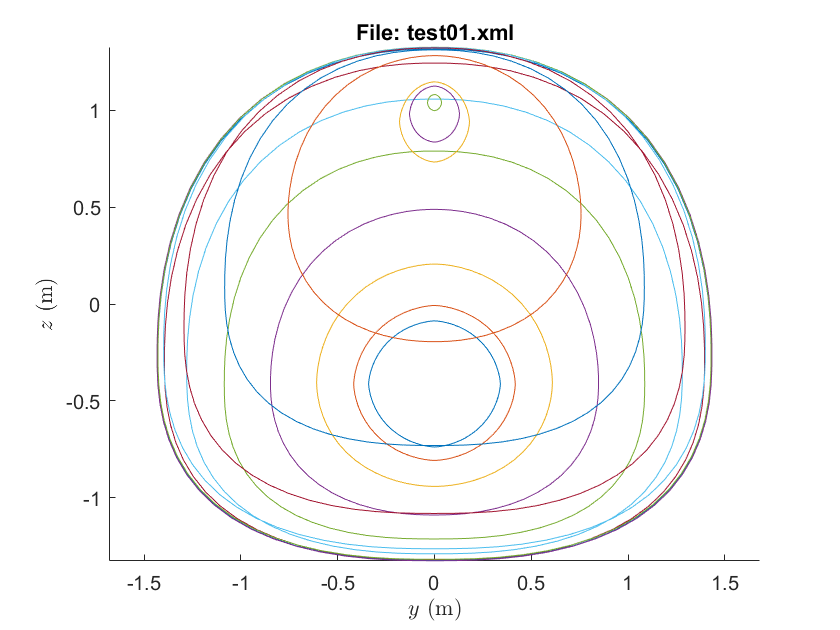

h2 = figure(2);
hold on
for i = 1:length(dataXYZ_B)
    axis equal
    plot(dataXYZ_B{i}(:,2),dataXYZ_B{i}(:,3))
end
title(sprintf('File: %s', fileName), 'Interpreter', 'none')
xlabel('$y$ (m)', 'Interpreter', 'latex'); 
ylabel('$z$ (m)', 'Interpreter', 'latex'); 
hold off